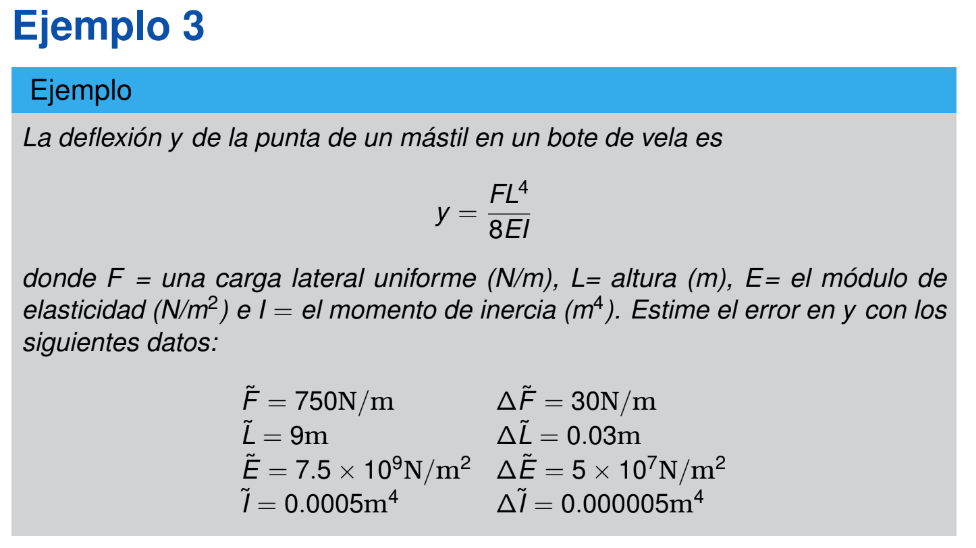

syms F L E I

y = @(F,L,E,I) (F*L^(4) / (8*E*I))

y = function_handle with value:
    @(F,L,E,I)(F*L^(4)/(8*E*I))


F_val = 750;
L_val = 9;
E_val = 7.5 * 10^(9);
I_val = 0.0005;

eaF = 30;
eaL = 0.03;
eaE = 5 * 10^(7);
eaI = 0.000005;


dy_dF = matlabFunction(diff(y,F))

dy_dF = function_handle with value:
    @(E,I,L)L.^4./(E.*I.*8.0)


dy_dL = matlabFunction(diff(y,L))

dy_dL = function_handle with value:
    @(E,F,I,L)(F.*L.^3)./(E.*I.*2.0)


dy_dE= matlabFunction(diff(y,E))

dy_dE = function_handle with value:
    @(E,F,I,L)(1.0./E.^2.*F.*L.^4.*(-1.0./8.0))./I


dy_dI = matlabFunction(diff(y,I))

dy_dI = function_handle with value:
    @(E,F,I,L)(F.*1.0./I.^2.*L.^4.*(-1.0./8.0))./E


eay = abs(dy_dF(E_val,I_val,L_val)) * eaF + abs(dy_dL(E_val,F_val,I_val,L_val)) * eaL + abs(dy_dE(E_val,F_val,I_val,L_val)) * eaE + abs(dy_dI(E_val,F_val,I_val,L_val)) * eaI

eay = 0.0115